% Creat FIS
fuzzyFIS = mamfis(...
    'Name', 'Use Binary MFs', ...
    'NumInputs', 2, 'NumInputMFs', 2, ...
    'NumOutputs', 1, 'NumOutputMFs', 3, ...
    'AddRule', 'none'...
    );

% Update Input 
fuzzyFIS.Inputs(1).Name = 'Angle';
fuzzyFIS.Inputs(1).Range = [-45, 45]

fuzzyFIS =   mamfis with properties:

                       Name: "Use Binary MFs"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


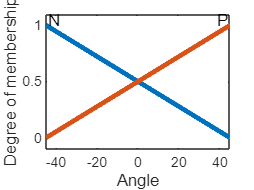

fuzzyFIS.Inputs(1).MembershipFunctions(1).Name = 'N';
fuzzyFIS.Inputs(1).MembershipFunctions(1).Type = 'trapmf';
fuzzyFIS.Inputs(1).MembershipFunctions(1).Parameters = [-45, -45, -45, 45];
fuzzyFIS.Inputs(1).MembershipFunctions(2).Name = 'P';
fuzzyFIS.Inputs(1).MembershipFunctions(2).Type = 'trapmf';
fuzzyFIS.Inputs(1).MembershipFunctions(2).Parameters = [-45, 45, 45, 45];

% Plot Input MFs
plotmf(fuzzyFIS, 'input', 1, 1000)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);


% Update Input 
fuzzyFIS.Inputs(2).Name = 'Velocity';
fuzzyFIS.Inputs(2).Range = [-50, 50]

fuzzyFIS =   mamfis with properties:

                       Name: "Use Binary MFs"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


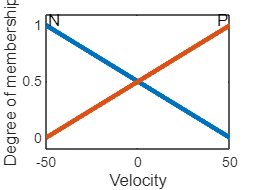

fuzzyFIS.Inputs(2).MembershipFunctions(1).Name = 'N';
fuzzyFIS.Inputs(2).MembershipFunctions(1).Type = 'trapmf';
fuzzyFIS.Inputs(2).MembershipFunctions(1).Parameters = [-50, -50, -50, 50];
fuzzyFIS.Inputs(2).MembershipFunctions(2).Name = 'P';
fuzzyFIS.Inputs(2).MembershipFunctions(2).Type = 'trapmf';
fuzzyFIS.Inputs(2).MembershipFunctions(2).Parameters = [-50, 50, 50, 50];

% Plot Input MFs
plotmf(fuzzyFIS, 'input', 2, 1000)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);


% Update Output 
fuzzyFIS.Outputs(1).Name = 'PWM';
fuzzyFIS.Outputs(1).Range = [-255, 255]

fuzzyFIS =   mamfis with properties:

                       Name: "Use Binary MFs"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


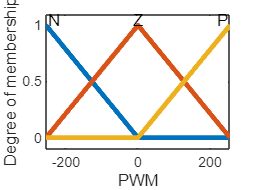

fuzzyFIS.Outputs(1).MembershipFunctions(1).Name = 'N';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Type = 'trapmf';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Parameters = [-255, -255, -255, 0];
fuzzyFIS.Outputs(1).MembershipFunctions(2).Name = 'Z';
fuzzyFIS.Outputs(1).MembershipFunctions(2).Type = 'trapmf';
fuzzyFIS.Outputs(1).MembershipFunctions(2).Parameters = [-255, 0, 0, 255];
fuzzyFIS.Outputs(1).MembershipFunctions(3).Name = 'P';
fuzzyFIS.Outputs(1).MembershipFunctions(3).Type = 'trapmf';
fuzzyFIS.Outputs(1).MembershipFunctions(3).Parameters = [0, 255, 255, 255];

% Plot Input MFs
plotmf(fuzzyFIS, 'output', 1, 1000)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);


% Specify Rules
rules = [...
    "If Angle is N and Velocity is N then PWM is P";...
    "If Angle is P and Velocity is N then PWM is Z";...
    "If Angle is N and Velocity is P then PWM is Z";...
    "If Angle is P and Velocity is P then PWM is N"...
    ];
fuzzyFIS = addRule(fuzzyFIS, rules)

fuzzyFIS =   mamfis with properties:

                       Name: "Use Binary MFs"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×4 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


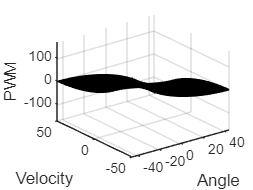


% Show control surface
options = gensurfOptions;
options.NumGridPoints = 900;

gensurf(fuzzyFIS, options);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 3);
grid on

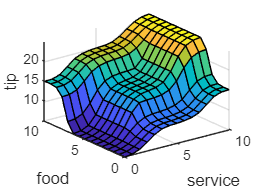


gensurf(readfis('tipper'))